# Example 7

The the current in the RC circuit has the transform


$$i(t)=\frac{1/RC}{s+1/RC}$$


If $R=1$ M$\Omega$ and $C=10$ $\mu$F, determine:

(a) The initial current $i\left(0\right)$.

(b) The time constant $\tau$.

(c) The time at which the current decays to 1% of $i(0)$.

## Solution

R = 1e6; C = 10e-6;
sigma = -1/(R*C);

(a) $i(0) = 1/RC$ so

i0 = 1/(R*C) % A

i0 =    0.100000000000000


(b) The time constant $\tau =\frac{1}{|\sigma |}$

tau = 1/abs(sigma) % seconds

tau =     10


(c) $T_{1\%} \approx 4.6 \tau$

T1pc = 4.6*tau

T1pc =     46


Plot solution to confirm the results

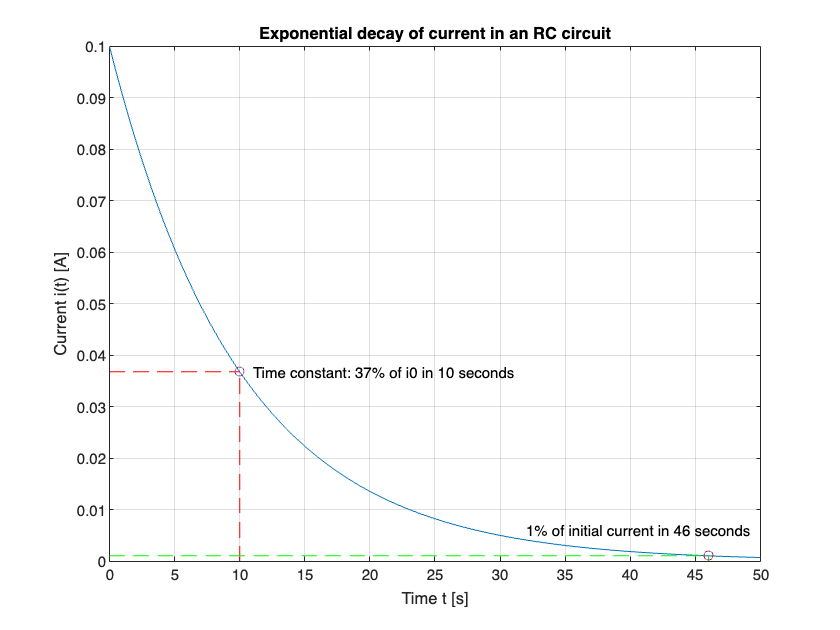

t = linspace(0,50,100);
plot(t,i0*exp(sigma*t)),grid
% Plot and label lines: time constant
line([tau,tau],[0,i0*exp(-1)],'Color','r','LineStyle','--')
line([0,tau],[i0*exp(-1),i0*exp(-1)],'Color','r','LineStyle','--')
text(tau+1,i0*exp(-1),'Time constant: 37% of i0 in 10 seconds')
hold on 
plot(tau,i0*exp(-1),'o')
% Plot and label lines: 1% point
line([4.6*tau,4.6*tau],[0,0.01*i0],'Color','g','LineStyle','--')
line([0,4.6*tau],[0.01*i0,0.01*i0],'Color','g','LineStyle','--')
plot(4.6*tau,0.01*i0,'o')
text(32,0.01*i0+0.005,'1% of initial current in 46 seconds')
% Label graph
title('Exponential decay of current in an RC circuit'),
ylabel('Current i(t) [A]'),xlabel('Time t [s]')
hold off